# Notebook - first implementation of phase field model

## Motivation

The standard solid diffusion model in BattMo uses Fick's law to describe lithium transport inside electrode particles. This works well for many materials, but breaks down for phase-separating materials like LiFePO4 (LFP).

In LFP, lithium does not diffuse smoothly across the particle. Instead, two distinct phases coexist : a lithium-rich phase and a lithium-poor phase, separated by a sharp interface. As the battery charges or discharges, this interface moves through the particle. Fick's law cannot capture this behavior.

The Cahn-Hilliard equation [1] is a natural replacement. It describes both diffusion and phase separation within a single unified framework, without needing to track the interface explicitly. This notebook presents a first implementation of the Cahn-Hilliard phase field model in BattMo, following the approach of Han et al. [2].

## The Cahn-Hilliard model

The Cahn-Hilliard model describes the time evolution of the lithium concentration $$c(\textbf{x}, t) \in [0, 1]$, where $c = 0$ is the delithiated phase and $c = 1$ is the fully lithiated phase. 

The model is built around a free energy functional that accounts for both the local thermodynamics and the energy cost of having concentration gradients : $$$
F(c) = \int_\Omega \left[  f_{hom}(c) + \frac{\varepsilon^2}{2}|\nabla c|^2  \right] dV
$$$.

The parameter $\varepsilon
$ controls the thickness of the interface between phases. A small $\varepsilon
$ gives a sharp interface, a large $\varepsilon
$ gives a diffuse one.

The concentration evolves according to : $\frac{\partial c}{\partial t} = \nabla \cdot \left( M(c) \nabla w \right)$ where $w$ is the chemical potential : $w = \frac{\partial f_{hom}}{\partial c} - \varepsilon^2 \nabla^2 c
$ and $M(c)$ is the mobility. 

We use the standard degenerate form $M(c) = c(1-c)$, which vanishes at $c = 0$ and $c = 1$, keeping the concentration physically bounded [3].

In practice, we split this fourth-order PDE into two coupled second-order equations, which are easier to discretize numerically. This is the formulation implemented in BattMo.

## Free energy and spinodal decomposition

The homogeneous free energy fhomf_{hom} fhom� determines whether the system tends to phase-separate or remain mixed. We use the mean-field expression from Han et al. : $f_{hom}(c) = \Omega c(1-c) + kT \left[ c \ln c + (1-c) \ln(1-c) \right]$.

The first term is the interaction energy, controlled by $\Omega$. The second term is the entropy of mixing, which always favors a homogeneous state and diverges at $c=0$ and $c=1$.

When $\Omega$ is large enough, the interaction energy overcomes the entropy and the free energy develops a double-well shape with two minima. A system with a concentration between these minima is thermodynamically unstable and spontaneously separates into two phases. This is called spinodal decomposition.

The condition for spinodal decomposition is $\Omega > 2kT$. When this holds, the spinodal points are : $c_\pm = \frac{1}{2} \pm \frac{1}{2}\sqrt{1 - \frac{2kT}{\Omega}}c\pm =21\pm 211-\Omega 2kT$.��

Any uniform concentration between $c_-$� and $c_+$ is unstable. In our model we use $\Omega = 2.29$ and $kT=1$, giving $c_- \approx 0.3$and $c_+ \approx 0.7$. The code below plots the free energy and marks the spinodal points.

filename = fullfile(battmoDir(), 'Electrochemistry', 'PhaseField', 'jsonfiles', 'phasefield.json');
jsonstruct = parseBattmoJson(filename);
jsonstruct.np = 3;

inputparams = PhaseFieldInputParams(jsonstruct);
model = PhaseField(inputparams);

simsetup = setupPhaseFieldSimulation(jsonstruct);

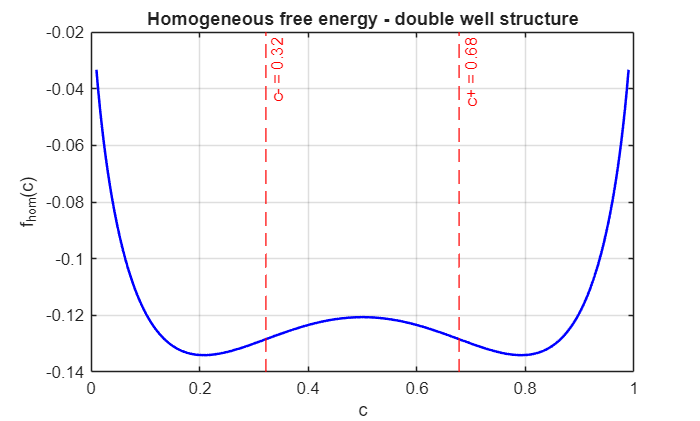

% test nodes
%% Free energy and spinodal points
omega  = simsetup.model.omega;
kT     = simsetup.model.kT;

c_test = linspace(0.01, 0.99, 300)';
f_hom  = omega .* c_test .* (1 - c_test) ...
       + kT .* (c_test .* log(c_test) + (1 - c_test) .* log(1 - c_test));

c_minus = 0.5 - 0.5 * sqrt(1 - 2*kT/omega);
c_plus  = 0.5 + 0.5 * sqrt(1 - 2*kT/omega);

figure;
plot(c_test, f_hom, 'b-', 'LineWidth', 1.5);
xline(c_minus, 'r--', sprintf('c- = %.2f', c_minus), 'LineWidth', 1);
xline(c_plus,  'r--', sprintf('c+ = %.2f', c_plus),  'LineWidth', 1);
xlabel('c');
ylabel('f_{hom}(c)');
title('Homogeneous free energy - double well structure');
grid on;

## Chebyshev spectral method

To discretize the spatial operators in the Cahn-Hilliard equation, we use the Chebyshev pseudo-spectral method, as described in Trefethen [4] and Boyd [5], and applied to phase field models in the context of Li-ion batteries by Han et al. [3]. This approach is particularly well-suited for phase field models because its error decays exponentially with the number of grid points, unlike finite difference or finite element methods, which have only algebraic convergence. This property, known as spectral accuracy, allows accurate resolution of sharp interfaces with a relatively small number of degrees of freedom.

The concentration field is expanded in a truncated Chebyshev series : $c(x, t) \approx \sum_{i=0}^{N} \alpha_i(t)  T_i(x)$ where $T_i(x)$ are the Chebyshev polynomials of the first kind [4], and $\alpha_i(t)$ are the time-dependent spectral coefficients. The spatial domain is $x \in [-1, 1] $.

The collocation points, also called Chebyshev-Gauss-Lobatto nodes, are defined as : $x_j = \cos\left(\frac{\pi j}{N}\right), \quad j = 0, \dots, N$.

These points are non-uniformly distributed, with a higher density near the boundaries. This clustering near the boundaries naturally resolves the steep concentration gradients that form at the interfaces between phases, which is a key advantage of Chebyshev grids over uniform grids [4].

In the pseudo-spectral (collocation) approach [5], the residual of the PDE is required to vanish exactly at the N+1 collocation nodes. This leads to a system of N+1 ODEs for the spectral coefficients $\alpha_i(t)$ which is integrated in time by BattMo's implicit solver [2].

The spatial operators are represented by three dense matrices of size (N+1)*(N+1), computed once at model setup using the three-term recurrence relation for Chebyshev polynomials [4] :


$$A_{ji} = T_{i-1}(x_{j-1}), \quad \mathbf{c} = A \,  \mathbf{\alpha}$$



$$dA_{ji} = T'_{i-1}(x_{j-1}), \quad \partial_x \mathbf{c} = dA  \,\mathbf{\alpha}$$



$$ddA_{ji} = T''_{i-1}(x_{j-1}), \quad \partial^2_x \mathbf{c} = ddA  \, \mathbf{\alpha}$$
